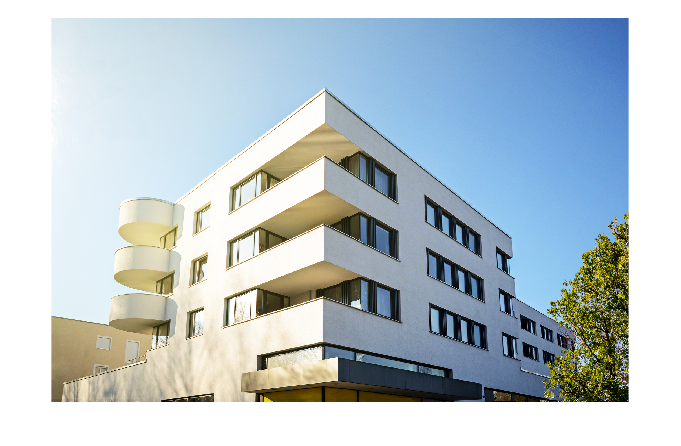

a= imread('my_buil.jpg');
imshow(a)

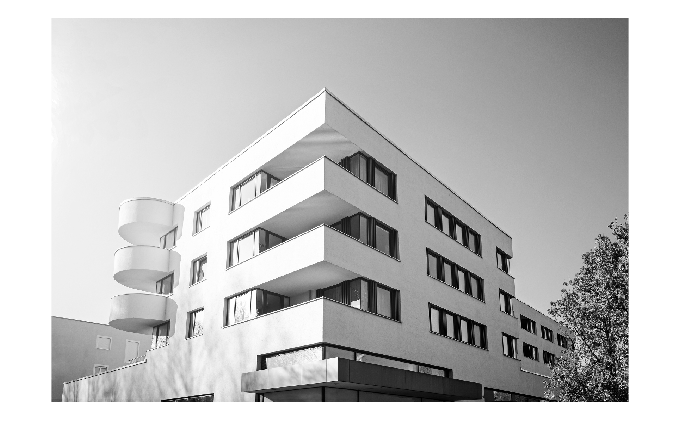

a2= im2gray(a);
imshow(a2)

corners= detectHarrisFeatures(a2)

corners =   3185×1 cornerPoints array with properties:

    Location: [3185×2 single]
      Metric: [3185×1 single]
       Count: 3185


corners.Location

ans = 3185×2 single matrix
1.0e+03 *

    0.0454    1.3457
    0.0960    1.3322
    0.1853    1.2881
    0.1999    1.2894
    0.2066    1.2844
    0.2130    1.1283
    0.2185    1.1804
    0.2892    1.2603
    0.2886    1.2740
    0.2958    1.2586


corners.Metric

ans = 3185×1 single column vector
    0.0026
    0.0016
    0.0017
    0.0010
    0.0024
    0.0035
    0.0011
    0.0053
    0.0012
    0.0032


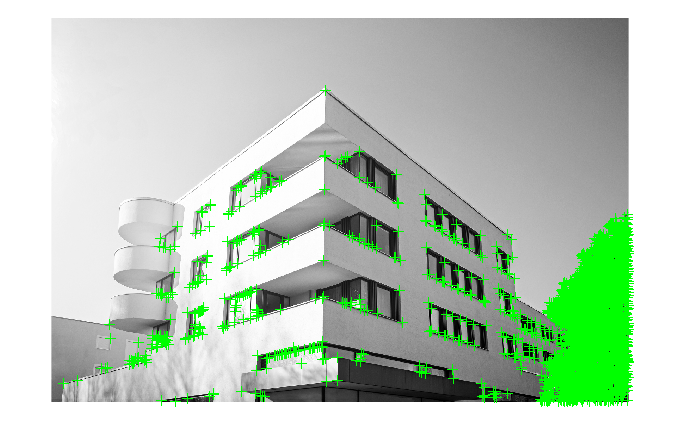

imshow(a2)
hold on
plot(corners)
hold off

imshow(a2)
hold on
strong_corners= selectStrongest(corners,200)

strong_corners =   200×1 cornerPoints array with properties:

    Location: [200×2 single]
      Metric: [200×1 single]
       Count: 200


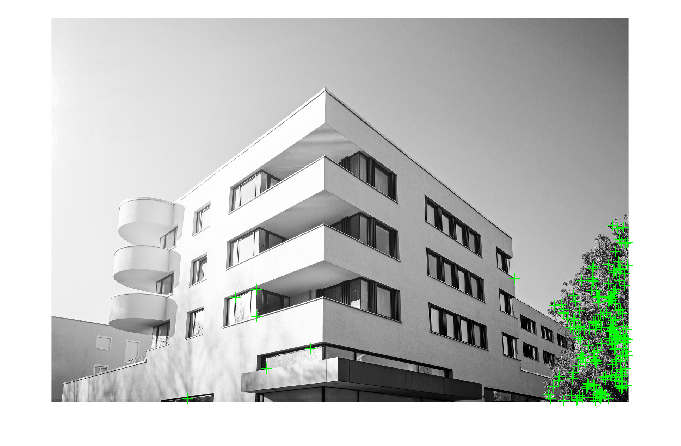

plot(strong_corners)
hold off